# **Analytical Design, Control Systems Lag Lead and PID Compensators**

   Topics:** Lag Lead, and PID** with comparison to autotuned compensation in matlab 

By Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

For Robust Controls 8352 | Dr. Guvenc | The Ohio State University | 10/25/2022

## Introduction

    In this report, analytical design discussed in Control of Mechatronic Systems by Levent Guvenc is used to design a lead lag and PID controller for a **sevo motor** - accessible within the automated driving lab at Ohio State. The following sections are a mix of MATLAB code, generated plots, and comments. At the end, there is a comparison of the generated controllers from the analytical methods to a PID automatically tuned within Matlab. 

# Start of Script 

Clearing the Variables 

clc; clear; close all

#### Plant: Qube Servo Angular Position Plant, already in the Laplace Domain

%SISO System
num = 28; den = [0.1 1 0];
G = tf(num,den)

Plant Characteristics

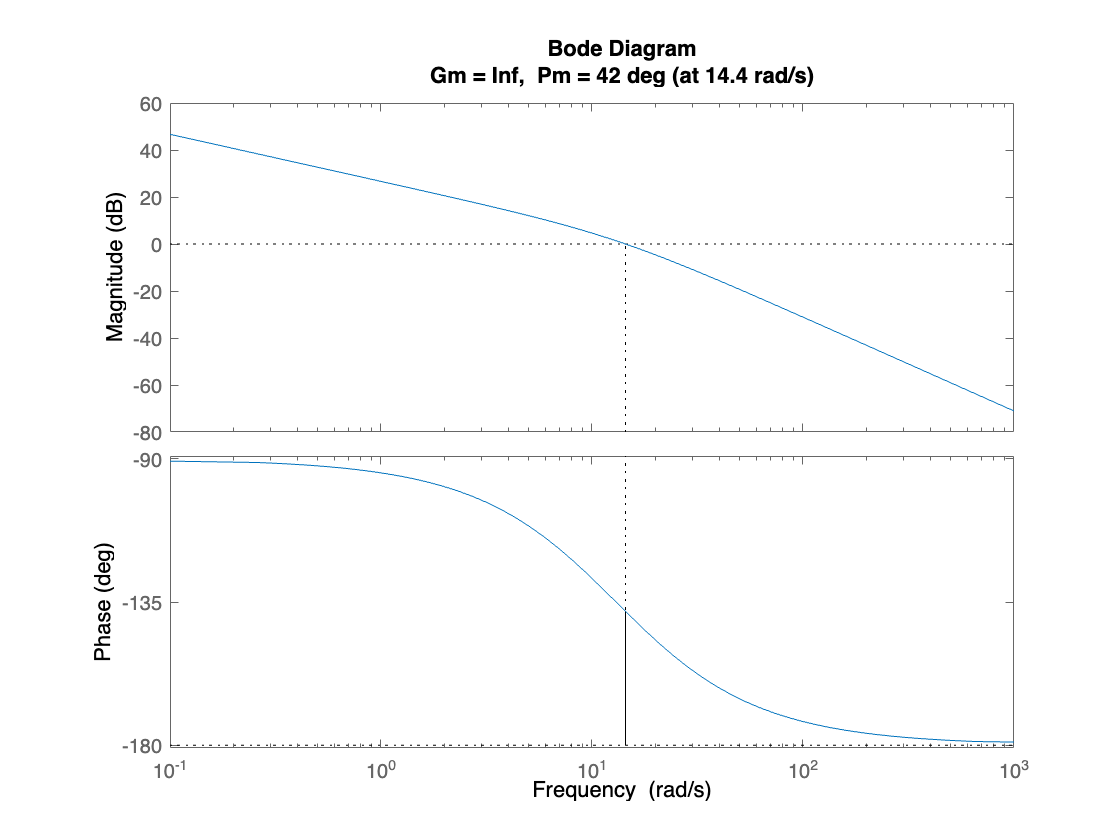

margin(G)

This is a second order system where G has one pole at the origin, also making the plant type 1.

Symbolic Plant

syms s; num = 28; den = 0.1*s^2+s;
sG = num/den;

**Inputs:  static  error  constant,  desired  bandwidth  (approximated  by  gain crossover frequency) and phase margin**. 

# Analytical Design of a Phase Lead Compensator (for lag lead control)

Choose a gain K from error constant specification

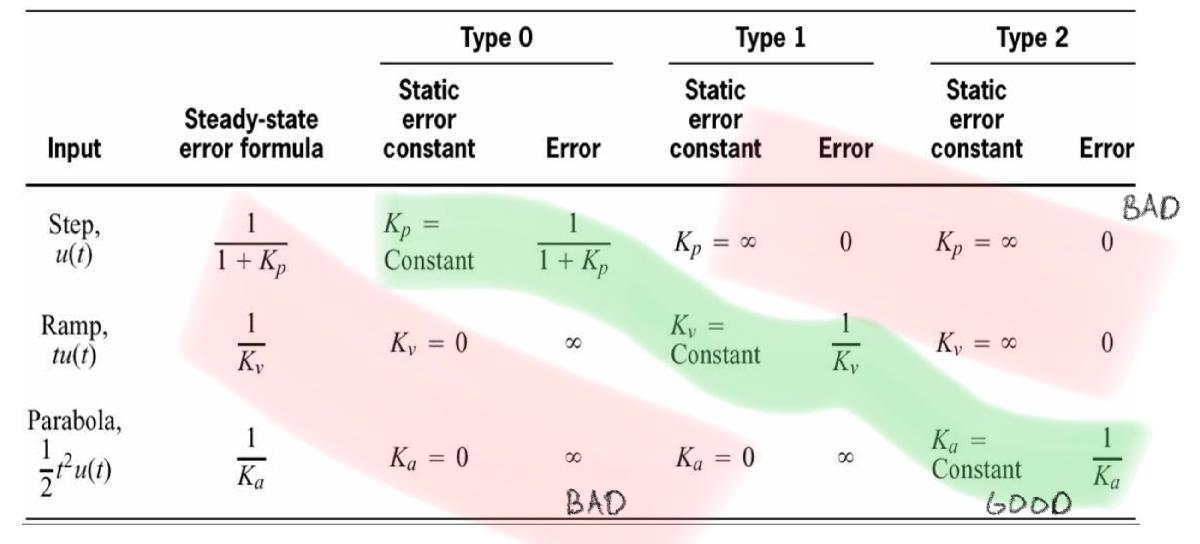

The Velocity Error Constant gives constant error for a type 1 system

Picking a Steady State Error and deriving the new gain

Kold = 28; %the current plant has a gain of 28
%RULE OF THUMB, do not increase the gain too much (as increasing the gain is asking for a smaller
%steady state error, which is less likely to be stable) 
sse = 0.03; %picking a desired steady state error
Knew = 1/sse; %from the table above
K=Knew/Kold; %what the current plant must be multiplied by
alpha_guess = 0.1;
KcAlpha = K;

The New Plant 

Gnew = K*G

Gnew =
 
       33.33
  ---------------
  0.1 s^2 + 1.3 s
 
Continuous-time transfer function.



The New Plants Margins and crossover frequencies

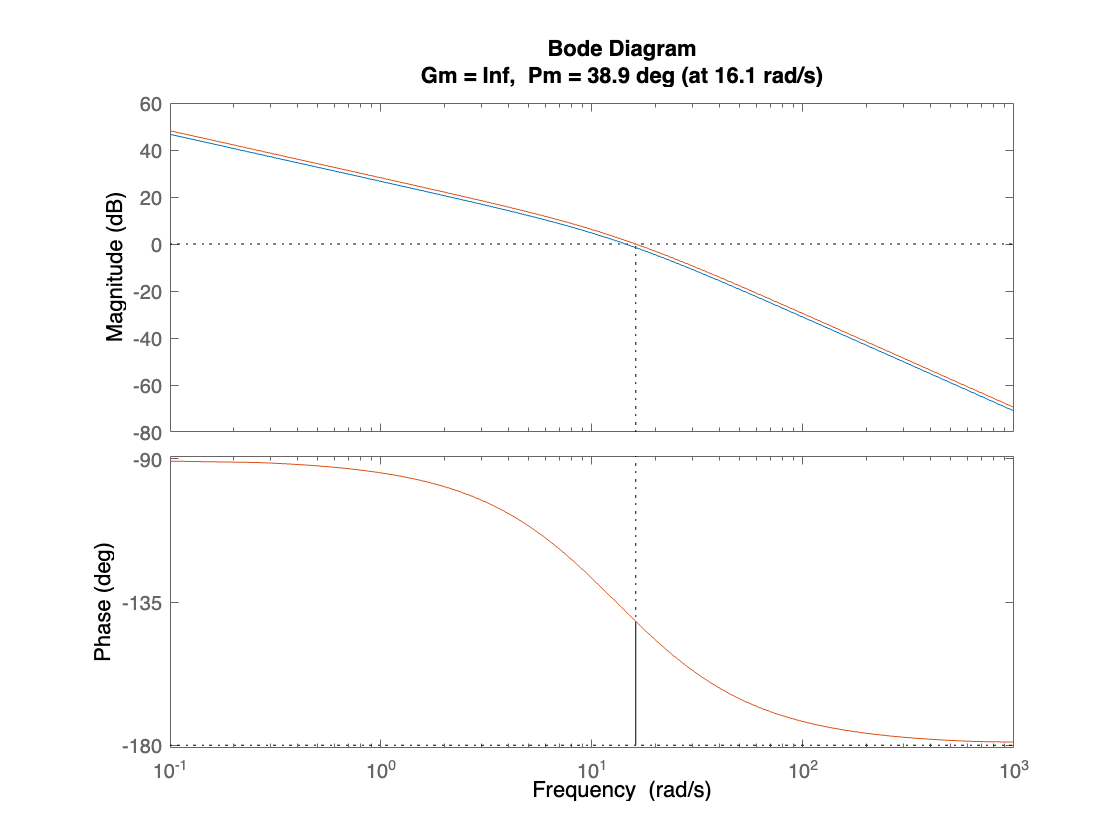

close all, figure(4), hold on, bode(G), margin(Gnew), hold off

The gain crossover approximates the current bandwidth

[Gm,Pm,W,WgainCrossover] = margin(Gnew)

Gm = Inf

Pm = 38.9102

W = Inf

WgainCrossover = 16.1052

Choose a new gain crossover smaller than the current crossover refrenced above 

wgc = WgainCrossover*2; %RULE OF THUMB: for Lead we want to increase gain crossover to improve bandwidth, maybe 2 to 5 or 10 times more. 

Lead Compensator Analytical Formula Design

%Revision Brian Lesko
PM=60; % desired phase margin in degrees
Gn = subs(sG,'s',[wgc*j]); % enter plant
theta=-180+PM-angle(Gn)*180/pi; % calculate required phase
    theta=theta*pi/180; % convert to radians
theta = double(theta);
% use formulas for control parameters
p=sin(theta)*wgc/(cos(theta)-KcAlpha*abs(Gn)); p=double(p);
z=sin(theta)*wgc/((1/KcAlpha/abs(Gn))-cos(theta)); z= double(z);
% substitute and check
s=tf('s');
alpha=z/p; % alpha of lead compensator
Kc=KcAlpha/alpha; % gain Kc of lead compensator
Cp=((1/z)*s+1)/((1/p)*s+1); % normalized lead compensator with unity dc gain
Clead=Kc*alpha*Cp; % lead compensator
max(pole(Clead*G))

ans = 0

pzplot(Clead*G), ax = gca; ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin';

Bode Plot Comparison G and G*Clead

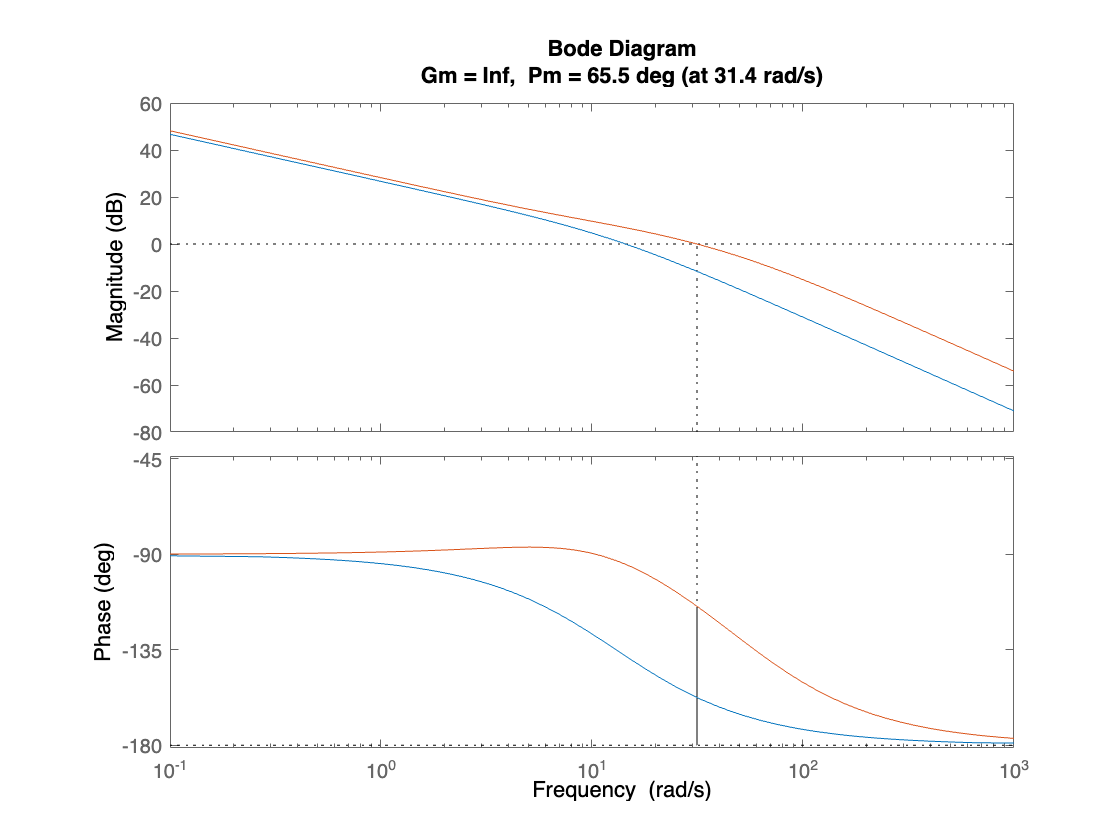

close all, figure(6), hold on, bode(G), margin(Clead*G), hold off

Bode of the Lead Controller

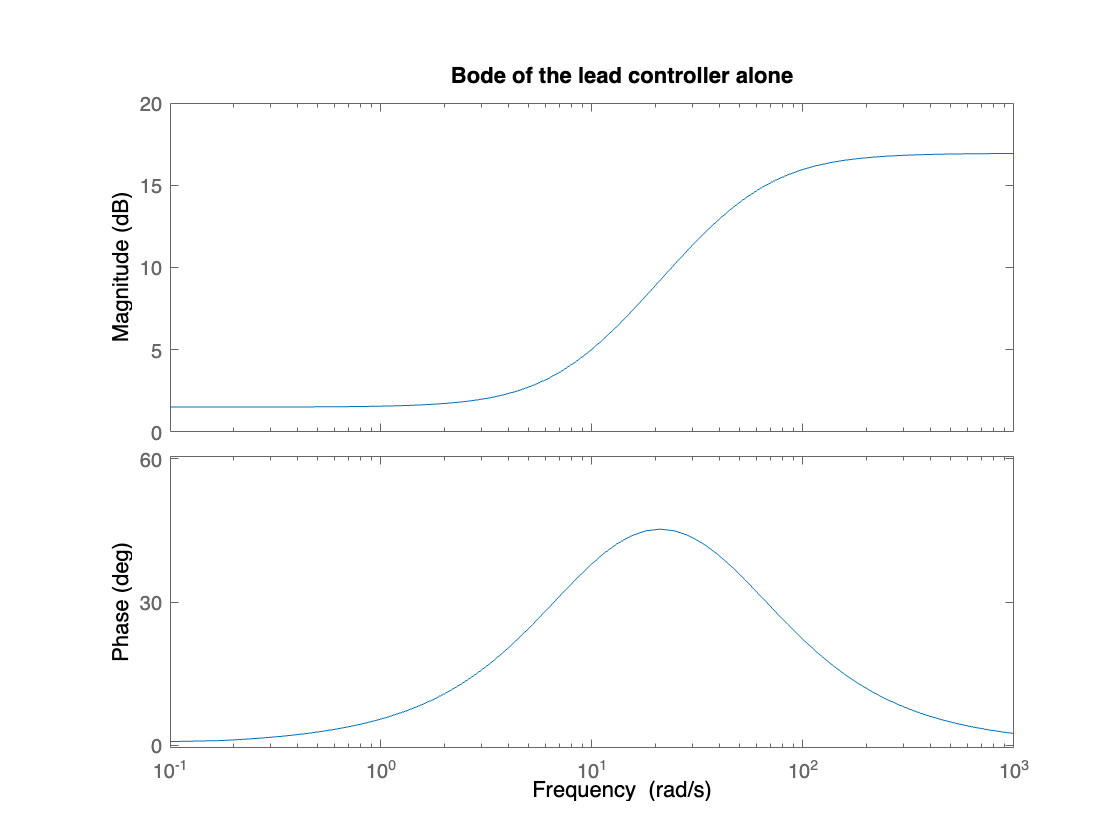

bode(Clead), title('Bode of the lead controller alone')

Step Response with The Lead Compensator

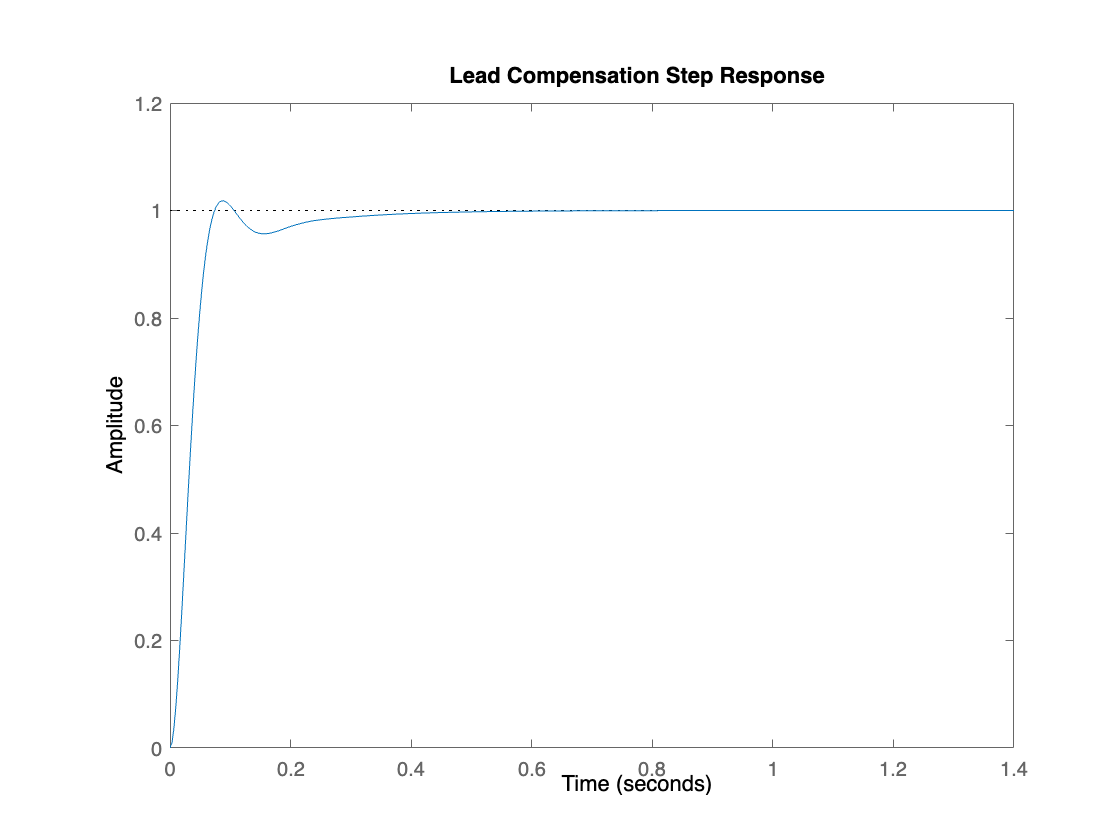

sys = feedback(G*Clead,1);
step(sys), title('Lead Compensation Step Response')

Everything looks as expected, the plant is stable and has a decent time response. 

# Analytical Design of a Phase Lag Compensator for the Lead System 

Static Error Constant Kp (Kp is for step) steady state error = 1/(1+Kp)

RULE OF THUMB. for lead lag, in the lag part, we only want to increase Kv, try 8*Kvold, OVERALL GAIN increased around 10. 

close all
KcBeta = 8;

Bode plot with KcAlpha Gain vs Original

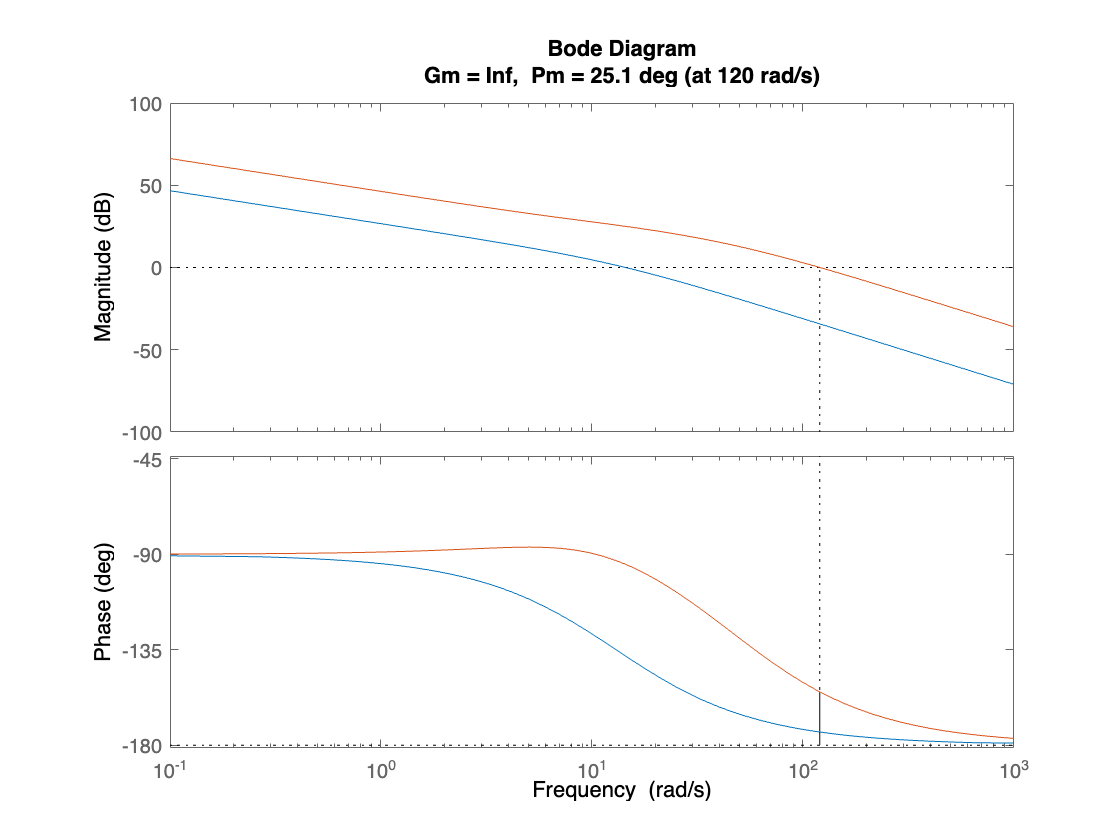

close all, figure(1), hold on, bode(G), margin(KcBeta*Clead*G)

bandwidth increase to account for phase lag's tendency to reduce bandwidth

[Gm,Pm,W,wgcold] = margin(G*KcBeta*Clead)

Gm = Inf

Pm = 25.1060

W = Inf

wgcold = 120.1920

wgc = wgcold*1;

Lag Compensator Analytical Formula Design

%Revision: Brian Lesko
PM=80; % desired phase margin in degrees
%KcBeta=10; % static gain from error constant specification
%sn=wgc*j;
Gn = subs(sG,{'s'},[wgc*j]);
theta=-180+PM-angle(Gn)*180/pi; % calculate required phase
    theta=double(theta);
theta=theta*pi/180;% convert to radians
% use formulas for control parameters
p=sin(theta)*wgc/(cos(theta)-KcBeta*abs(Gn));
z=sin(theta)*wgc/((1/KcBeta/abs(Gn))-cos(theta));
    z = double(z); p = double(p);
% substitute and check
s=tf('s');
beta=z/p; % beta of lag compensator
Kc=KcBeta/beta; % gain Kc of lag compensator
Cp=((1/z)*s+1)/((1/p)*s+1); % normalized lag compensator with unity dc gain
Clag=Kc*beta*Cp % lag compensator

Clag =
 
   0.4279 s + 8
  ---------------
  0.0008619 s + 1
 
Continuous-time transfer function.



phase Lag vs original plant Bode plot

close all, hold on, figure(2), bode(G), margin(Clag*G*Clead);shg % check if desired PM and wgc are obtained

Bode of Lag Controller * Lead Controller

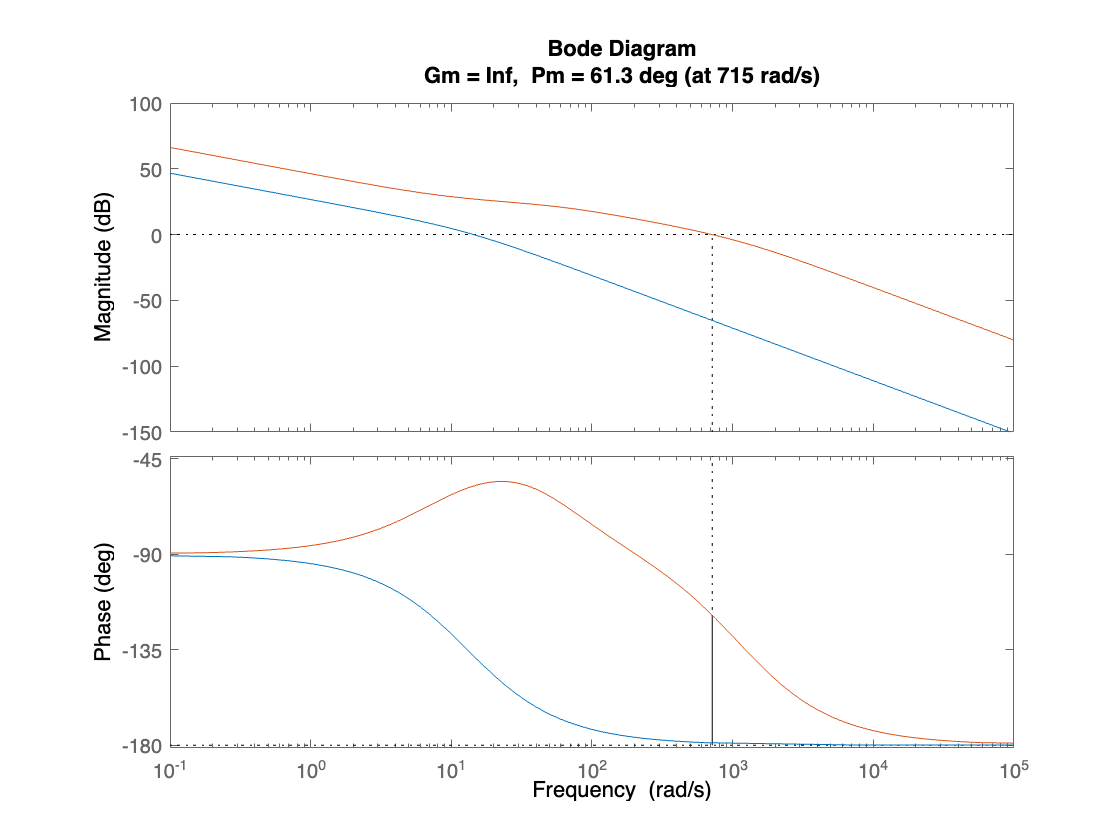

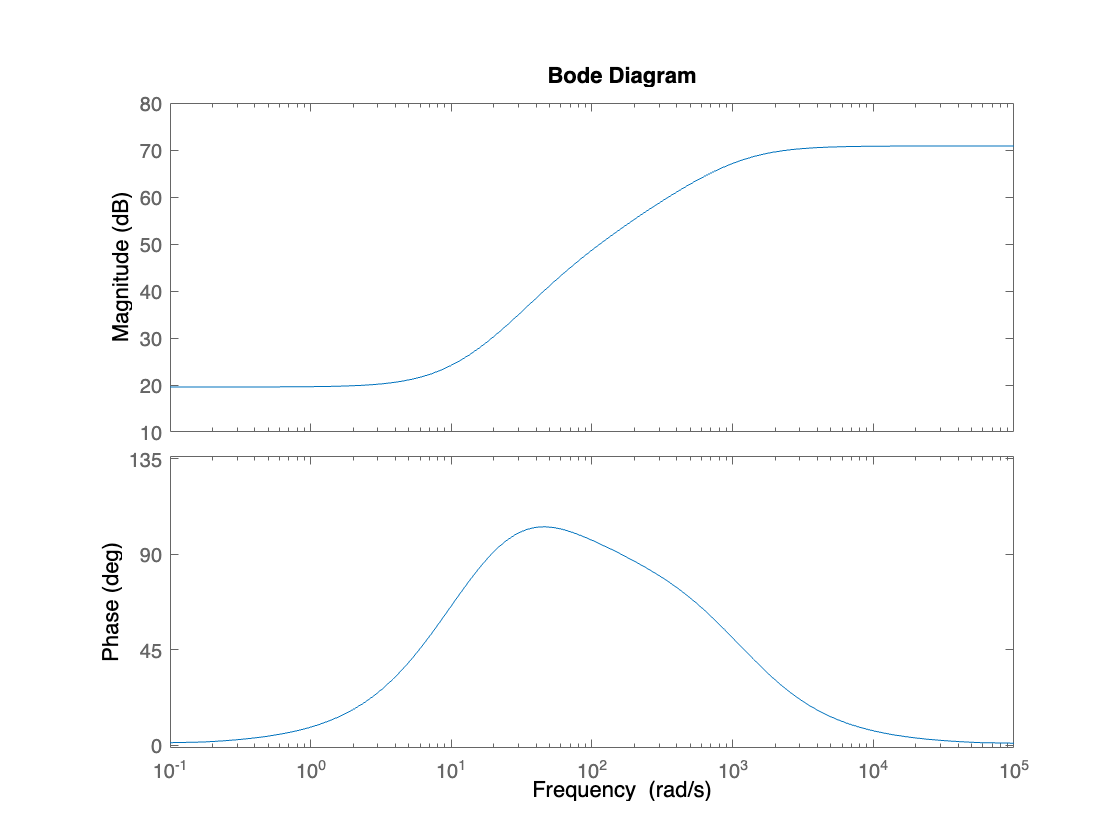

hold off, figure(3), bode(Clag*Clead)

Step of Lag Lead Compensated Plant

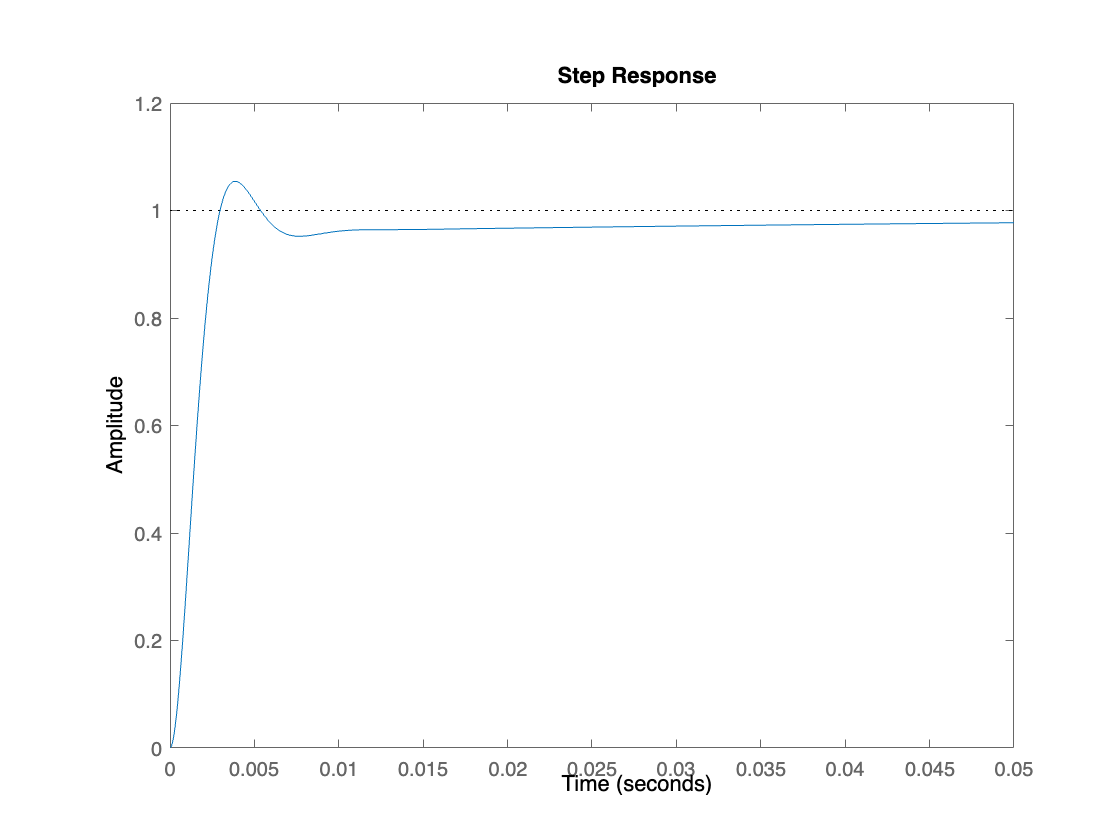

step(feedback(Clag*Clead*G,1))

This is the Lag Lead Controller analytical result, which looks as expected. 

# Analytical Design of a PID Controller

Error Constant Defines the Gain used 

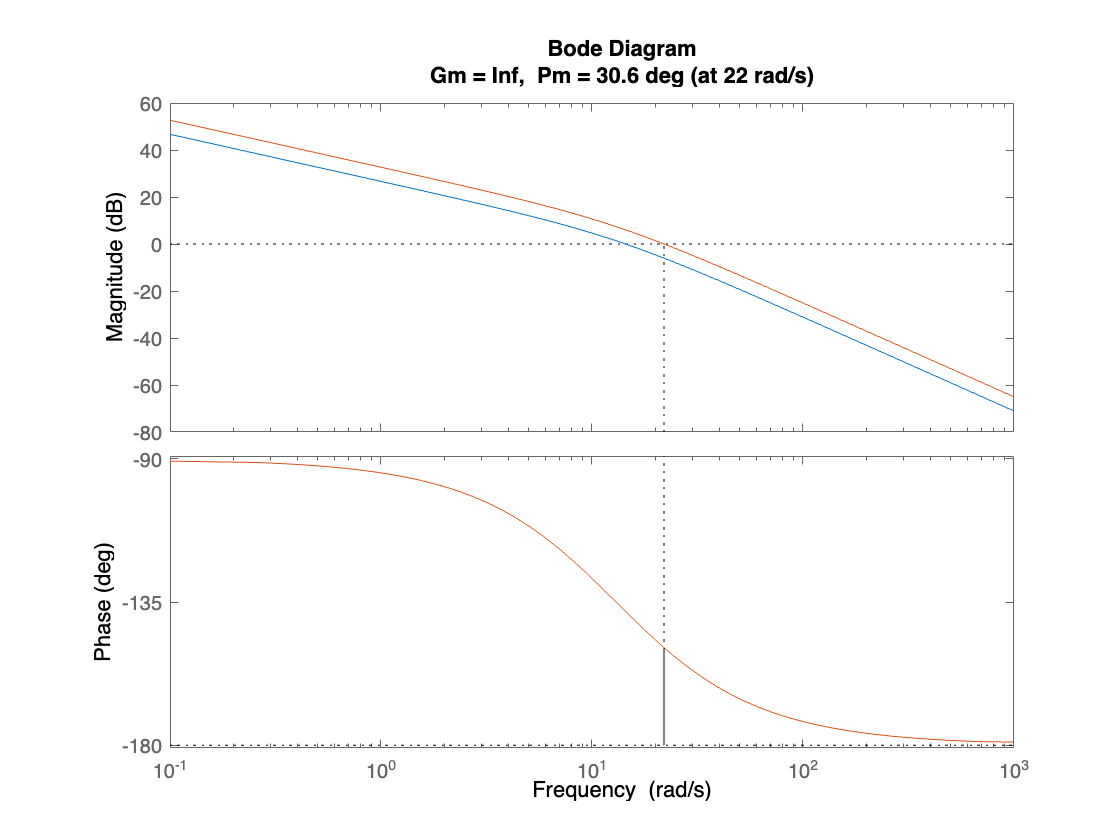

%The plant is Type 1, use some error constant
K = 2;
close all, figure(7), hold on, bode(G), margin(G*K)

The current Bandwidth can be increased

%increase 
wgc=22*4; % Enter desired gain crossover frequency in rad/s

PM=60; % Enter desired phase margin in degrees
Ki=1; % Integral gain based on error constant for PID
%%%
sn=wgc*j;
Gn = subs(sG,{'s'},[sn]); % Enter plant here
theta=-180+PM-angle(Gn)*180/pi;% This is the angle in degrees required from controller at wgc
    theta = double(theta);
theta=theta*pi/180; %Angle converted to radians for Matlab commands
Kp=cos(theta)/ abs(Gn);
    Kp=double(Kp); % Kp for PID – Change with other formula for different controller
Kd=Ki/wgc/wgc+sin(theta)/wgc/abs(Gn);
    Kd=double(Kd); % Kd for PID – Change with other formula for different controller
s=tf('s'); % Define s as Laplace transform variable for transfer functions
Cpid=(Kd*s*s+Kp*s+Ki)/s

Cpid =
 
  0.2545 s^2 + 16.55 s + 1
  ------------------------
             s
 
Continuous-time transfer function.



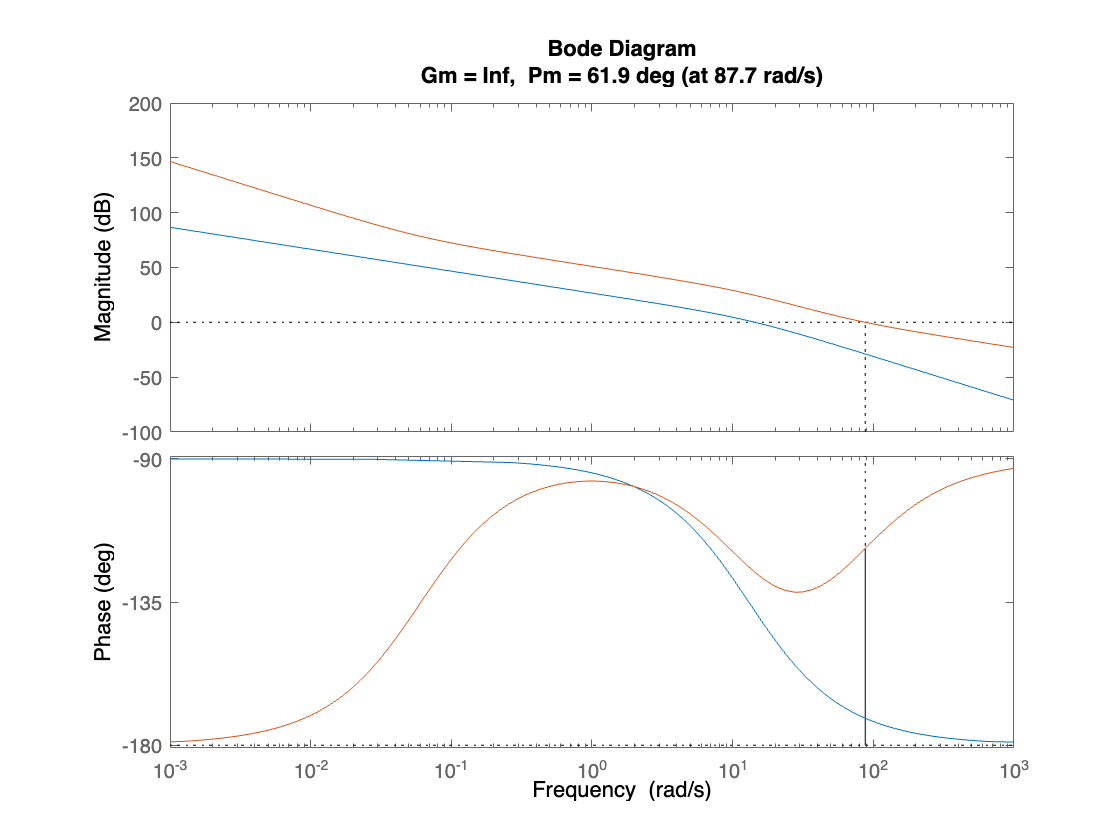

close all, figure(8), hold on, bode(G), margin(G*Cpid)

PID Step Response

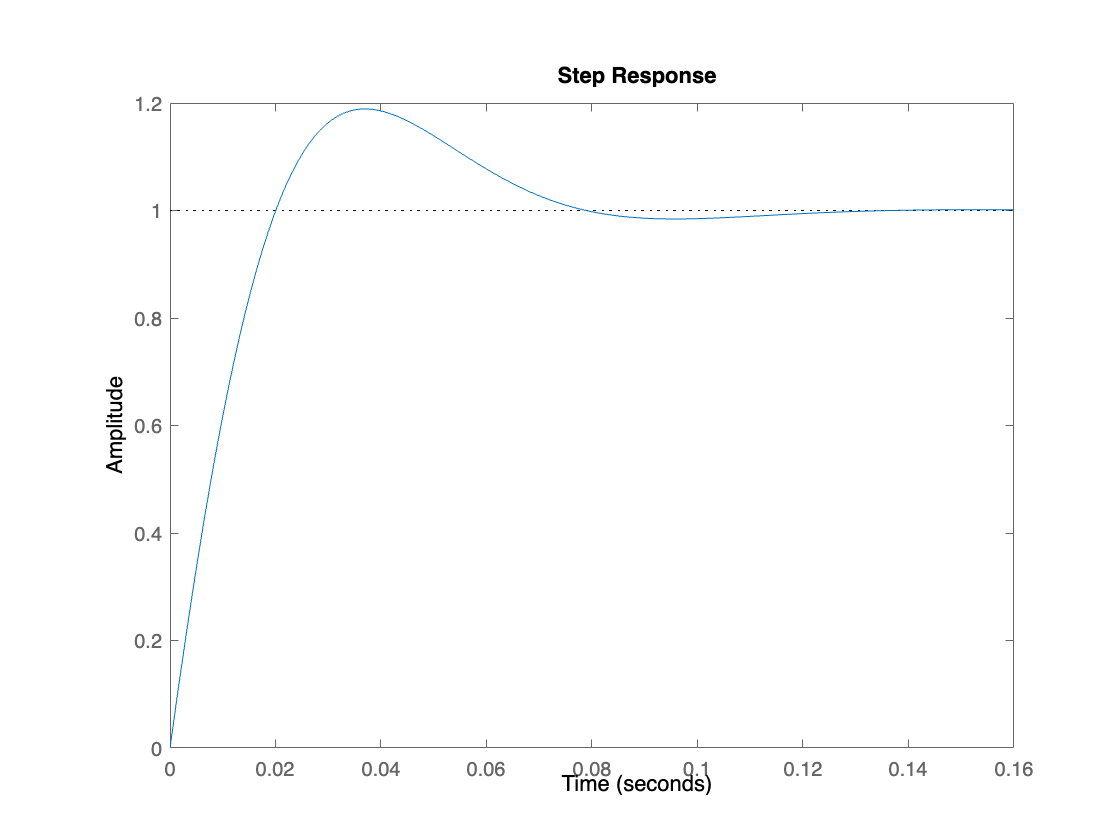

close all, figure(9), hold on, step(feedback(Cpid*G,1))

## Automatic Tuned PID from Matlab 

The Generated Controller

Cpidtune = pidtune(G,'PID');

Matlab Tuned PID Bode plot

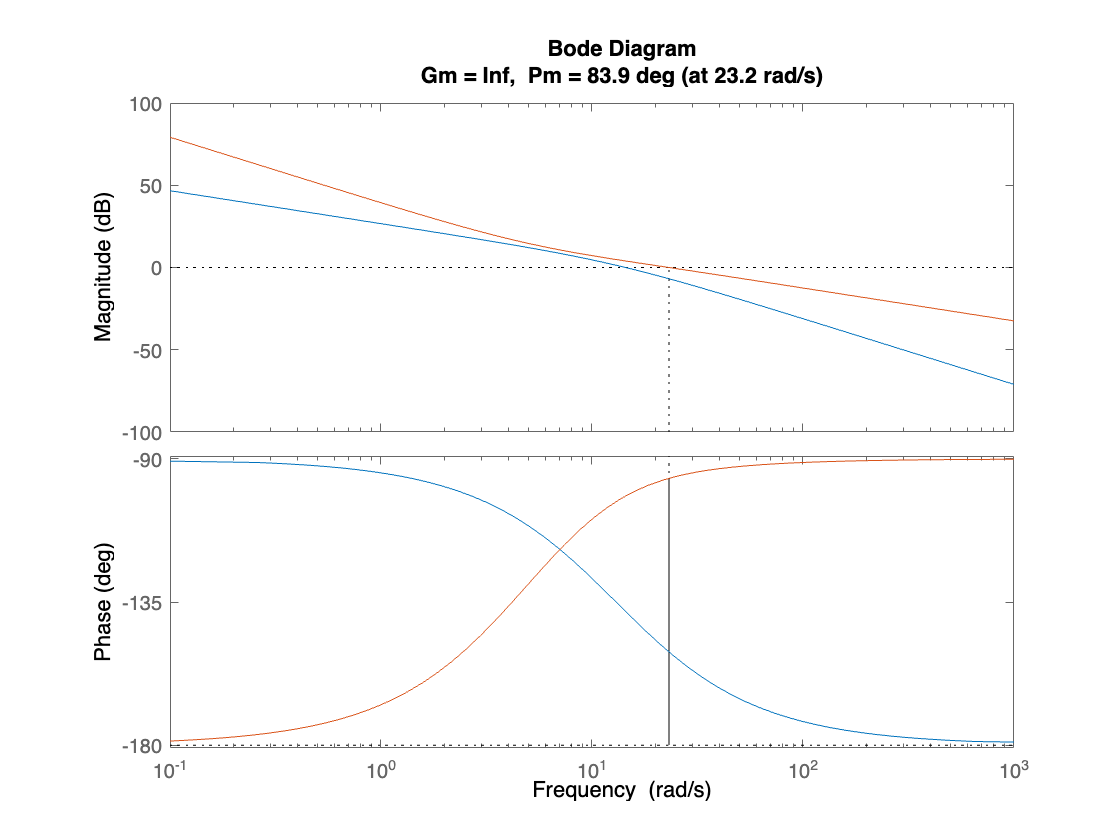

close all, figure(10), hold on, bode(G), margin(G*Cpidtune)

Matlab Tuned PID Step Response

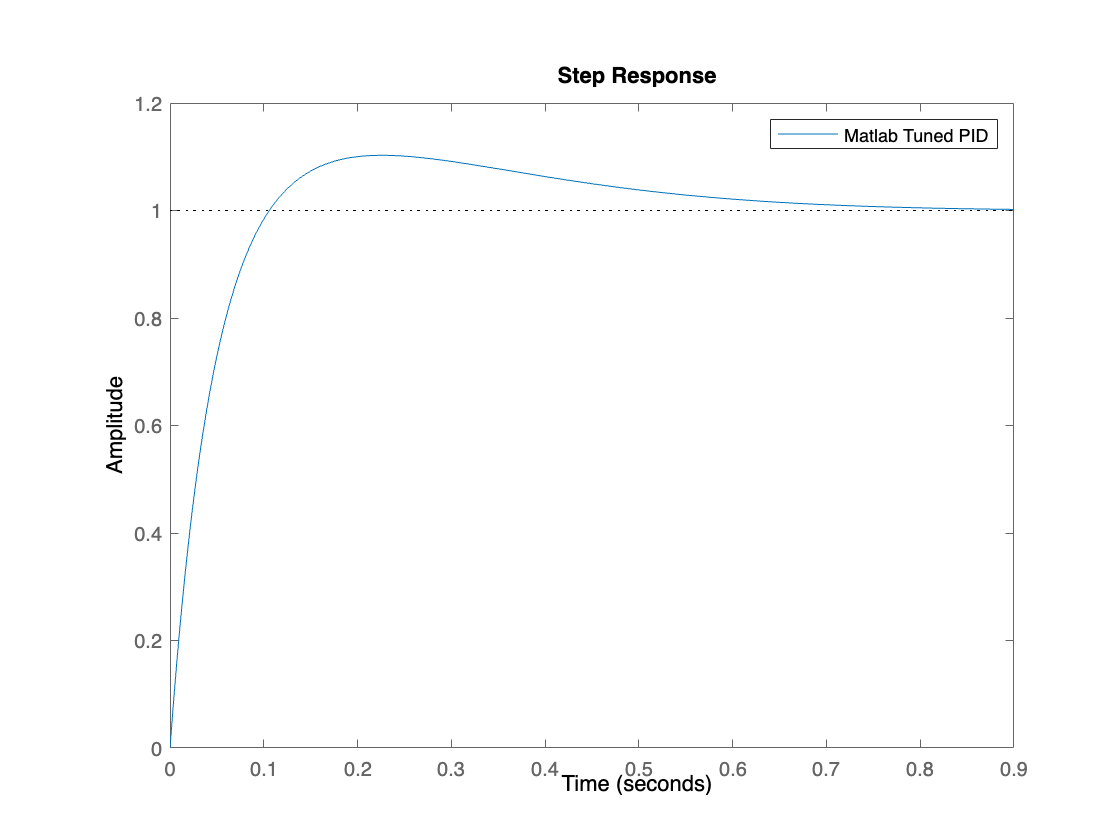

close all, figure(11), hold on, step(feedback(Cpidtune*G,1)), legend('Matlab Tuned PID')

## Change the Time Constants: at 10% 20% 30% increases and evaluate the change in performance of each design

The Current Plant, G, is a second order plant. Second order plants have the general form 

syms a Wn zeta s
G_2nd_order = a*Wn^2 / ( s^2 + 2*zeta*Wn*s + Wn^2)

$$G\_2nd\_order = \frac{{\mathrm{Wn}}^{2}\,a}{{\mathrm{Wn}}^{2}+2\,\zeta \,\mathrm{Wn}\,s+s^{2}}$$

Where Tau, the time constant, is equal to 1/(zeta*wn) 

current_zeta_x_Wn = 1/2; current_tau = 1/current_zeta_x_Wn;

The second order plant in terms of tau is 

s=tf('s');
G_2nd_order_tau = 28 / (0.1*s^2 + 2*(1/current_tau)*s)

G_2nd_order_tau =
 
      28
  -----------
  0.1 s^2 + s
 
Continuous-time transfer function.



Creating new Plants with 10% 20% and 30% increases in the time constant, tau

G_tau_10_percent_increase = 28 / (0.1*s^2 + 2*(1/current_tau*1.1)*s);
G_tau_20_percent_increase = 28 / (0.1*s^2 + 2*(1/current_tau*1.2)*s);
G_tau_30_percent_increase = 28 / (0.1*s^2 + 2*(1/current_tau*1.3)*s);
%Putting the plants into an array variable
Gtau(1) = G;
Gtau(2) = G_tau_10_percent_increase;
Gtau(3) = G_tau_20_percent_increase;
Gtau(4) = G_tau_30_percent_increase;

The new plants to test are: 

Gtau

Gtau =
 
  From input 1 to output:
        28
  ---------------
  0.1 s^2 + 1.3 s
 
  From input 2 to output:
        28
  ---------------
  0.1 s^2 + 1.1 s
 
  From input 3 to output:
        28
  ---------------
  0.1 s^2 + 1.2 s
 
  From input 4 to output:
        28
  ---------------
  0.1 s^2 + 1.3 s
 
Continuous-time transfer function.



The following figures were created by running the above script 4 times with the respective tau value, saving the values using the following system, and commenting out the beginning variable clearing. 

C_lag_tau(i) = Clag

C_lead_tau(i) = Clead

C_pid_tau(i) = Cpid

Gtau(i)

This section can only be run with the downloaded plants and controllers saved from the previous step

Loading the plants and controllers

load('C_pid_tau.mat'); load('C_lead_tau.mat'); load('C_lag_tau.mat'); load('Gtau.mat'); 

Creating the feedback systems 

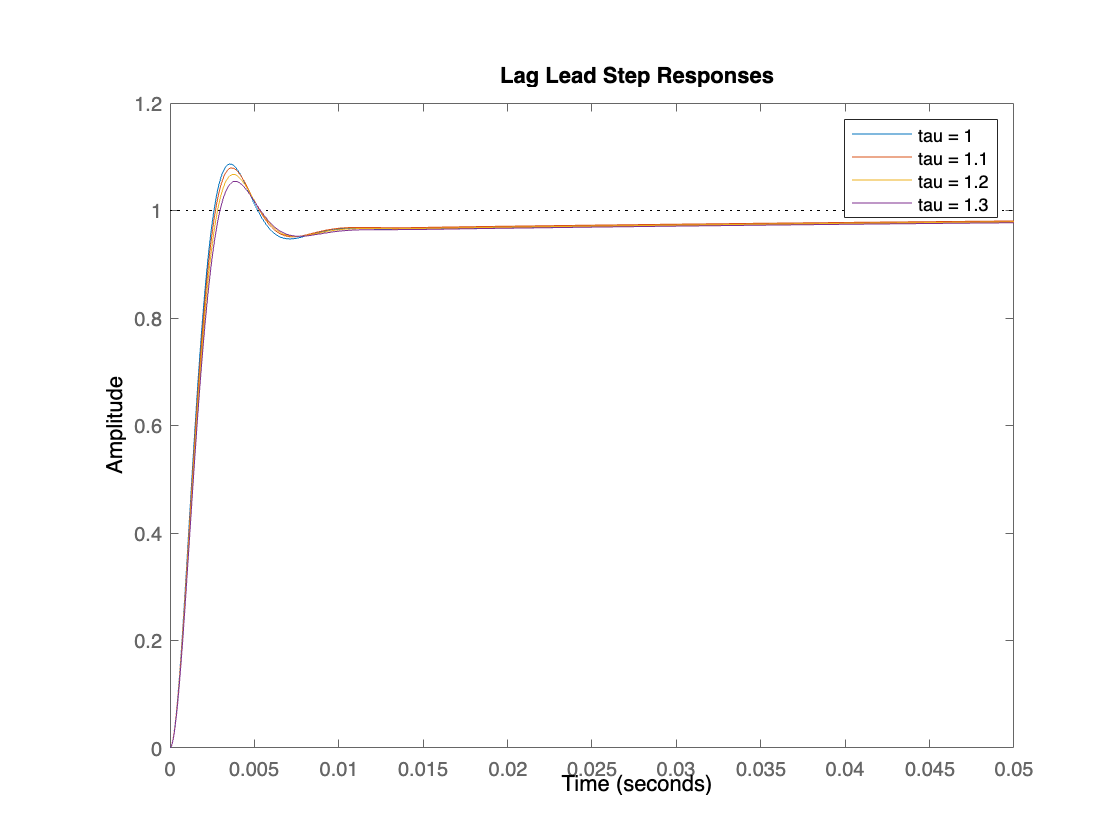

for i = 1:4
    LagLeadsys(i) = feedback( C_lag_tau(i)*C_lead_tau(i)*Gtau(i) ,1 );
    PIDsys(i) = feedback( C_pid_tau(i)*Gtau(i) , 1 );
end 
figure(), step(LagLeadsys(1),LagLeadsys(2),LagLeadsys(3),LagLeadsys(4))
title('Lag Lead Step Responses'), legend('tau = 1','tau = 1.1','tau = 1.2','tau = 1.3'), hold off

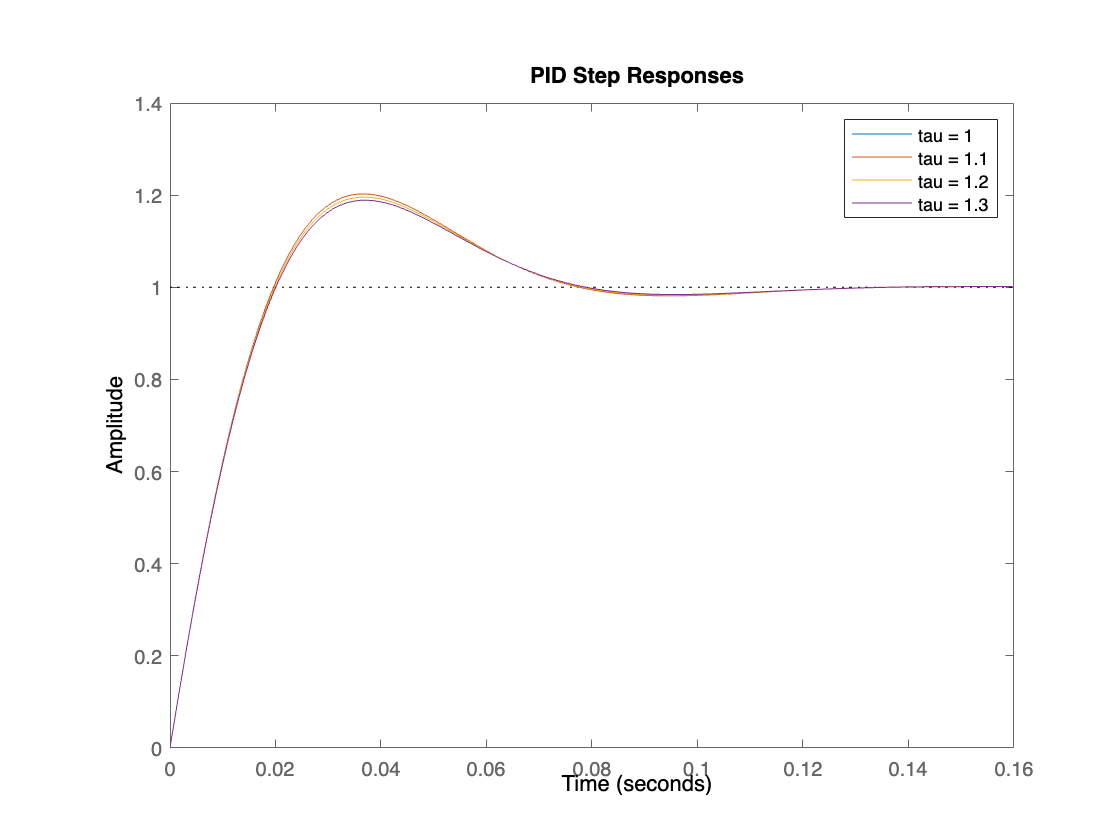

figure(), step(PIDsys(1),PIDsys(2),PIDsys(3),PIDsys(4))
title('PID Step Responses'), legend('tau = 1','tau = 1.1','tau = 1.2','tau = 1.3')

It seems that the choice for the time constant has a somewhat small impact on the step response for this plant, especially for the PID controller